clear; clc;

% --- Parameters ---
data_folder = '/Users/manoharpaturi/Desktop/EEE S2 Proj/TestCasesLibrary_Measurement/Forced oscillation/Case 1F';
dt = 40 / 1200; % Time step (s)
expected_gens = 29; % Expected number of generators
fixed_rank = 29; % Force 29 modes
reg_param = 1e-2; % Regularization parameter for DMD

% --- Load Data ---
try
    [Xraw, num_gens] = load_data(data_folder, dt);
    if num_gens ~= expected_gens
        error('Number of generators (%d) does not match expected (%d).', num_gens, expected_gens);
    end
    fprintf('Number of generators: %d\n', num_gens);
catch e
    error('Failed to load data: %s', e.message);
end

Raw data size for rotor_speeds.csv: 1201 rows, 29 columns
Loaded rotor_speeds.csv: 1201 rows, 29 columns
Raw data size for rotor_angles.csv: 1201 rows, 29 columns
Loaded rotor_angles.csv: 1201 rows, 29 columns
Final Xraw: 29 signals, 2402 time steps


Number of generators: 29



% --- Prepare DMD Inputs ---
Xraw = Xraw - mean(Xraw, 2); % Remove mean
X1 = Xraw(:, 1:end-1); % Snapshot t
X2 = Xraw(:, 2:end); % Snapshot t+1
t = (0:size(Xraw, 2)-1) * dt; % Time vector

% --- Rank Selection ---
try
    [U, S, V] = svd(X1, 'econ');
    singular_values = diag(S);
    r = min(fixed_rank, length(singular_values));
    if r < fixed_rank
        warning('Only %d singular values available; using rank %d.', length(singular_values), r);
    end
    fprintf('Selected rank for DMD: %d\n', r);
catch e
    error('SVD failed: %s', e.message);
end

Selected rank for DMD: 29



% --- Initial Modes for Streaming DMD (from Exact DMD) ---
try
    Ur = U(:, 1:r); Sr = S(1:r, 1:r); Vr = V(:, 1:r);
    Atilde = Ur' * X2 * Vr / Sr;
    Atilde_reg = Atilde + reg_param * eye(size(Atilde));
    [Phi_reg, Lambda_reg] = eig(Atilde_reg);
    Phi = X2 * Vr / Sr * Phi_reg;
    lambda = diag(Lambda_reg);
catch e
    error('Initial Exact DMD failed: %s', e.message);
end

% --- Streaming DMD ---
try
    r_stream = r;
    Phi_stream = Phi(:, 1:r_stream); lambda_stream = lambda(1:r_stream);
    update_factor = 0.05;
    for k = 1:length(t)-1
        x1 = Xraw(:, k); x2 = Xraw(:, k+1);
        if norm(x1) > 1e-6
            A_update = x2 * pinv(x1);
            Phi_stream = Phi_stream + update_factor * (A_update * Phi_stream - Phi_stream * diag(lambda_stream));
            if cond(Phi_stream) < 1e6
                lambda_stream = eig(Phi_stream \ (A_update * Phi_stream));
                lambda_stream = lambda_stream(1:min(r_stream, length(lambda_stream)));
            else
                fprintf('Streaming DMD update at k=%d skipped due to ill-conditioned Phi_stream\n', k);
            end
        end
    end
    b_stream = pinv(Phi_stream) * X1(:, 1); % Mode amplitudes
    % Dimension checks
    assert(size(Phi_stream, 2) == length(b_stream), 'Streaming DMD: Phi and b dimensions mismatch');
    assert(length(b_stream) == length(lambda_stream), 'Streaming DMD: b and lambda dimensions mismatch');
    % Reconstruct data
    X_recon_stream = zeros(size(Xraw));
    for k = 1:length(t)
        X_recon_stream(:, k) = real(Phi_stream * (b_stream .* lambda_stream.^(k-1)));
    end
    error_stream = norm(Xraw - X_recon_stream, 'fro') / norm(Xraw, 'fro');
    % Analyze modes
    mode_props_stream = analyze_modes(Phi_stream, lambda_stream, abs(imag(log(lambda_stream)/dt))/(2*pi), ...
        -real(log(lambda_stream)/dt)./abs(log(lambda_stream)/dt), b_stream, num_gens);
catch e
    fprintf('Error in Streaming DMD: %s\n', e.message);
    error_stream = NaN;
    mode_props_stream = [];
end

Streaming DMD update at k=1 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=2 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=3 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=4 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=5 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=6 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=7 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=8 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=9 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=10 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=11 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=12 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=13 skipped due to ill-conditioned Phi_stream
Streaming DMD update at k=14 skipped due to ill-conditioned Phi_stream
Streaming DMD u


--- Streaming DMD ---


Reconstruction Error: 9.995005e-01


Modes (29 total):


    frequency    damping_ratio      energy      amplitude     dominant_generator
    _________    _____________    __________    __________    __________________

           0               1      9.0638e-52    3.0106e-26            16        
           0               1               0             0            16        
           0              -1               0             0            16        
     0.10882          0.3819               0             0            16        
     0.10882          0.3819               0             0            16        
     0.36173         0.15492               0             0            16        
     0.36173         0.15492               0             0            16        
      0.3766        0.004061               0             0            16        
      0.3766       

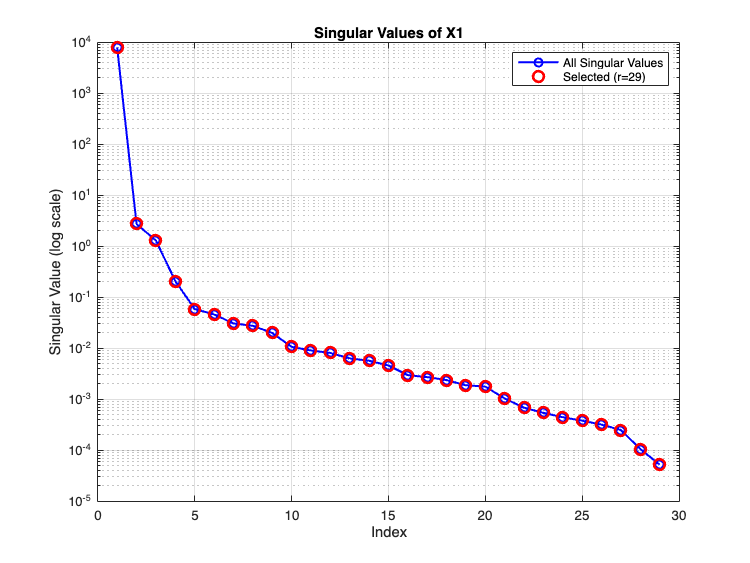

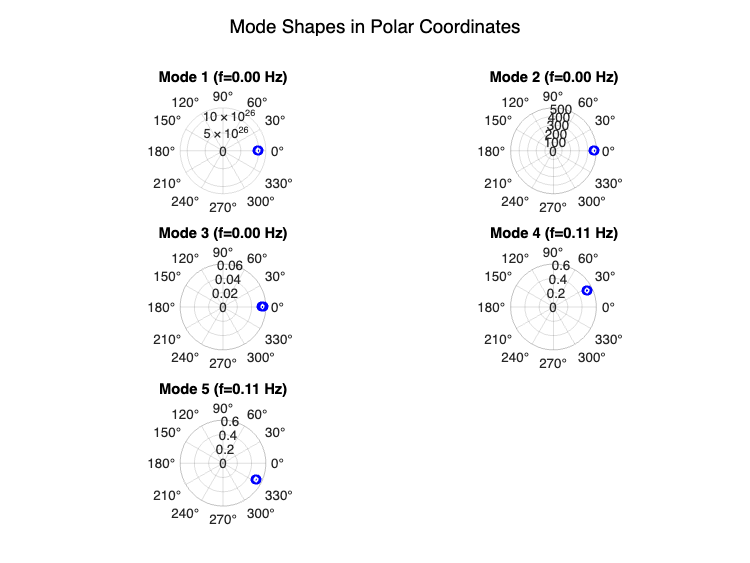

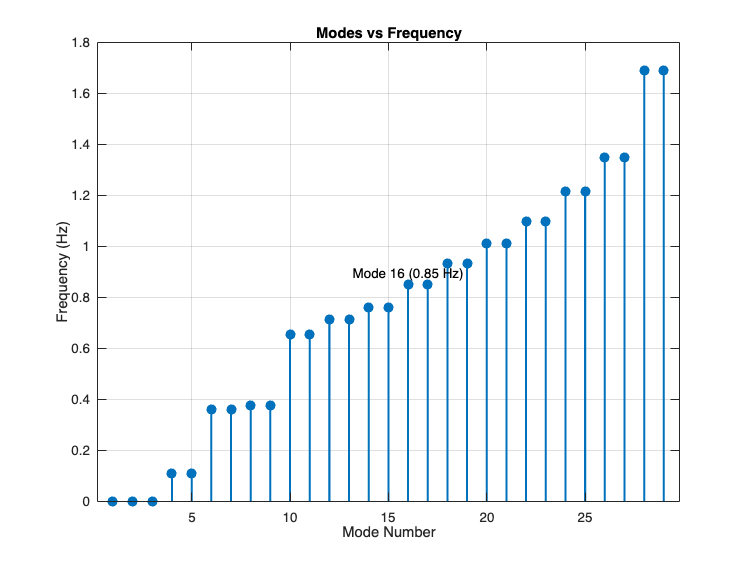


% --- Display Modes and Plots ---
if ~isnan(error_stream) && ~isempty(mode_props_stream) && height(mode_props_stream) > 0
    fprintf('\n--- Streaming DMD ---\n');
    fprintf('Reconstruction Error: %.6e\n', error_stream);
    fprintf('Modes (%d total):\n', height(mode_props_stream));
    
    % Compute dominant generators
    dominant_gen = zeros(height(mode_props_stream), 1);
    for j = 1:height(mode_props_stream)
        mode_shape = mode_props_stream.mode_shape{j}(1:num_gens);
        participation = calc_participation(mode_shape, num_gens);
        [~, max_gen] = max(participation);
        dominant_gen(j) = max_gen;
    end
    mode_props_stream.dominant_generator = dominant_gen;
    
    % Display table
    try
        disp(mode_props_stream(:, {'frequency', 'damping_ratio', 'energy', 'amplitude', 'dominant_generator'}));
    catch e
        fprintf('Error displaying table: %s\n', e.message);
    end
    
    % --- Plotting ---
    % Singular Values Plot
    try
        figure;
        semilogy(singular_values, 'bo-', 'LineWidth', 1.5);
        hold on;
        semilogy(singular_values(1:r), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
        title('Singular Values of X1', 'FontSize', 14);
        xlabel('Index', 'FontSize', 12);
        ylabel('Singular Value (log scale)', 'FontSize', 12);
        legend('All Singular Values', sprintf('Selected (r=%d)', r));
        grid on;
        set(gca, 'FontSize', 10);
    catch e
        fprintf('Error in singular values plot: %s\n', e.message);
    end
    
    % Mode Shapes in Polar Coordinates (first few modes)
    try
        num_modes_to_plot = min(5, height(mode_props_stream)); % Plot up to 5 modes
        figure;
        for j = 1:num_modes_to_plot
            subplot(ceil(num_modes_to_plot/2), 2, j);
            mode_shape = mode_props_stream.mode_shape{j}(1:num_gens);
            theta = angle(mode_shape); % Phase in radians
            rho = abs(mode_shape); % Magnitude
            polarplot(theta, rho, 'bo-', 'LineWidth', 1.5);
            title(sprintf('Mode %d (f=%.2f Hz)', j, mode_props_stream.frequency(j)), 'FontSize', 10);
            pax = gca;
            pax.ThetaAxisUnits = 'degrees';
            pax.FontSize = 10;
        end
        sgtitle('Mode Shapes in Polar Coordinates', 'FontSize', 14);
    catch e
        fprintf('Error in mode shapes plot: %s\n', e.message);
    end
    
    % Modes vs Frequency Plot
    try
        figure;
        mode_numbers = 1:height(mode_props_stream);
        stem(mode_numbers, mode_props_stream.frequency, 'filled', 'LineWidth', 1.5, 'MarkerSize', 6);
        title('Modes vs Frequency', 'FontSize', 14);
        xlabel('Mode Number', 'FontSize', 12);
        ylabel('Frequency (Hz)', 'FontSize', 12);
        grid on;
        % Label the mode closest to 0.86 Hz
        [~, idx_086] = min(abs(mode_props_stream.frequency - 0.86));
        text(mode_numbers(idx_086), mode_props_stream.frequency(idx_086)*1.05, ...
             sprintf('Mode %d (%.2f Hz)', idx_086, mode_props_stream.frequency(idx_086)), ...
             'FontSize', 10, 'HorizontalAlignment', 'center');
        set(gca, 'FontSize', 10);
    catch e
        fprintf('Error in modes vs frequency plot: %s\n', e.message);
    end
else
    fprintf('\n--- Streaming DMD ---\n');
    fprintf('Failed to compute modes.\n');
end


% --- Helper Functions ---

function [Xraw, num_gens] = load_data(data_folder, dt)
    file_names = {'rotor_speeds.csv', 'rotor_angles.csv'};
    Xraw = [];
    num_gens = 0;
    
    for i = 1:length(file_names)
        file_path = fullfile(data_folder, file_names{i});
        if exist(file_path, 'file')
            data = readmatrix(file_path, 'NumHeaderLines', 1);
            if size(data, 2) < 2
                warning('File %s has insufficient columns.', file_names{i});
                continue;
            end
            data = data(:, 2:end);
            fprintf('Raw data size for %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
            if contains(file_names{i}, 'rotor_speeds', 'IgnoreCase', true)
                num_gens = size(data, 2);
                mean_spd = mean(data(:));
                if mean_spd < 1
                    warning('Rotor speeds appear to be in per-unit (mean = %.4f). Converting to Hz assuming 60 Hz base.', mean_spd);
                    data = data * 60;
                end
            else
                max_val = max(abs(data(:)));
                if max_val > 0
                    data = data / max_val;
                else
                    data = zeros(size(data));
                end
            end
            Xraw = [Xraw; data];
            fprintf('Loaded %s: %d rows, %d columns\n', file_names{i}, size(data, 1), size(data, 2));
        else
            warning('File %s not found.', file_path);
        end
    end
    
    if isempty(Xraw)
        error('No data loaded.');
    end
    
    Xraw = Xraw';
    fprintf('Final Xraw: %d signals, %d time steps\n', size(Xraw, 1), size(Xraw, 2));
end

function mode_props = analyze_modes(Phi, lambda, freq_Hz, damping_ratio, b, num_gens)
    num_modes = length(lambda);
    mode_energy = abs(b).^2;
    amplitude = abs(b); % Amplitude is the magnitude of b
    
    mode_shapes = cell(num_modes, 1);
    for i = 1:num_modes
        mode_shapes{i} = Phi(:, i);
    end
    
    mode_props = table(...
        freq_Hz(:), damping_ratio(:), mode_energy(:), amplitude(:), mode_shapes, ...
        'VariableNames', {'frequency', 'damping_ratio', 'energy', 'amplitude', 'mode_shape'});
    
    mode_props = sortrows(mode_props, 'frequency');
end

function participation = calc_participation(mode_shape, num_gens)
    if length(mode_shape) < num_gens
        error('Mode shape length (%d) less than num_gens (%d).', length(mode_shape), num_gens);
    end
    mode = mode_shape(1:num_gens);
    norm_val = norm(mode);
    if norm_val > 1e-6
        normalized = mode / norm_val;
    else
        normalized = zeros(size(mode));
    end
    participation = abs(normalized).^2;
end